clear
% #923
syms x;
y=sinh(x)

$$y = \sinh\left(x\right)$$

M=[0 0]

M =      0     0


% Какой угол образует с осью абцисс касательная к кривой в точке M

Dy=diff(y)

$$Dy = \cosh\left(x\right)$$

DyM=subs(Dy,[x y],M)

$$DyM = 1$$

alpha=atan(DyM)

$$alpha = \frac{\pi }{4}$$

% #924
syms x real;
y=cosh(x/2)

$$y = \cosh\left(\frac{x}{2}\right)$$

x0=2*log(2)

x0 =    1.386294361119891


% Составить уравнения касательной и нормали к цепной линии

digits(3)
Dy=diff(y)

$$Dy = \frac{\sinh\left(\frac{x}{2}\right)}{2}$$

y0=vpa(subs(y,x,x0))

$$y0 = 1.25$$

Dy0=vpa(subs(Dy,x,x0))

$$Dy0 = 0.375$$

% Касательная
yk=y0+Dy0*(x-x0)

$$yk = 0.375\,x+0.73$$

% Нормаль
yn=y0-1/Dy0*(x-x0)

$$yn = 4.95-2.67\,x$$

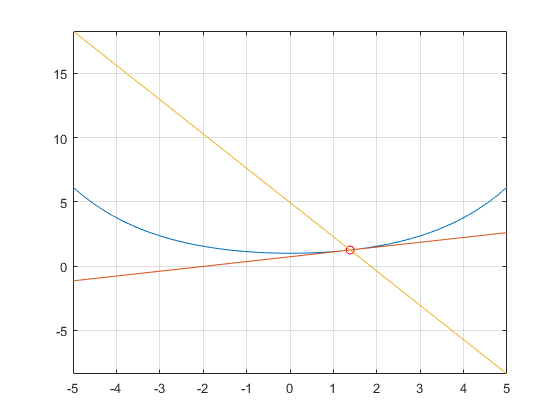

fplot(y)
hold on
plot(x0,y0,'ro')
fplot(yk)
fplot(yn)
grid
hold off

% #925
syms t xk xn t0;
x=cosh(t)

$$x = \cosh\left(t\right)$$

y=sinh(t)

$$y = \sinh\left(t\right)$$

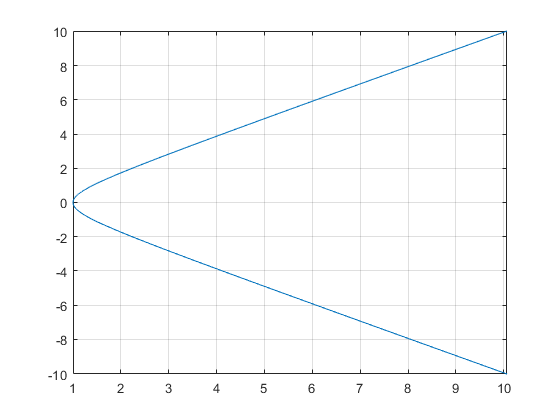

% Составить уравнение касательной к равносторонней гиперболе
% в точке t=t0

fplot(x,y,[-3 3])
grid

Dx=diff(x)

$$Dx = \sinh\left(t\right)$$

Dy=diff(y)

$$Dy = \cosh\left(t\right)$$

Dyx=Dy/Dx

$$Dyx = \frac{\cosh\left(t\right)}{\sinh\left(t\right)}$$

x0=subs(x,t,t0)

$$x0 = \cosh\left(t_{0}\right)$$

y0=subs(y,t,t0)

$$y0 = \sinh\left(t_{0}\right)$$

Dyx0=subs(Dyx,t,t0)

$$Dyx0 = \frac{\cosh\left(t_{0}\right)}{\sinh\left(t_{0}\right)}$$

yk=simplify(y0+Dyx0*(xk-x0))

$$yk = \frac{\mathrm{xk}\,\cosh\left(t_{0}\right)-1}{\sinh\left(t_{0}\right)}$$

pretty(yk)

xk cosh(t0) - 1
---------------
    sinh(t0)



yn=simplify(y0-1/Dyx0*(xn-x0))

$$yn = -\frac{\sinh\left(t_{0}\right)\,\left(\mathrm{xn}-2\,\cosh\left(t_{0}\right)\right)}{\cosh\left(t_{0}\right)}$$

pretty(yn)

  sinh(t0) (xn - 2 cosh(t0))
- --------------------------
           cosh(t0)



% #926
syms y x;
y1=x-x^2

$$y1 = x-x^{2}$$

y2=5*x

$$y2 = 5\,x$$

% Найти углы между заданными линиями

s=solve(y-x+x^2==0,y-5*x==0)

s = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


A=[s.x(1),s.y(1)]

$$A = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

B=[s.x(2),s.y(2)]

$$B = \left(\begin{array}{cc} -4 & -20 \end{array}\right)$$

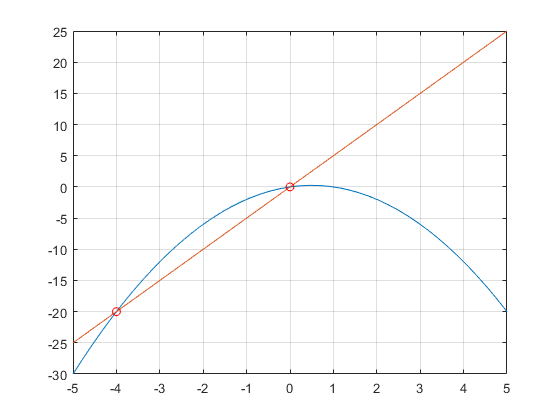

fplot(y1)
hold on
fplot(y2)
plot(A(1),A(2),'ro')
plot(B(1),B(2),'ro')
grid on
hold off

dy1=diff(y1)

$$dy1 = 1-2\,x$$

dy2=diff(y2)

$$dy2 = 5$$

% В точке A
k1_a=subs(dy1,x,A(1))

$$k1\_a = 1$$

k2_a=subs(dy2,x,A(1))

$$k2\_a = 5$$

tan_phi_a=(k2_a-k1_a)/(1+k1_a*k2_a)

$$tan\_phi\_a = \frac{2}{3}$$

phi_a=atan(tan_phi_a)

$$phi\_a = \mathrm{atan}\left(\frac{2}{3}\right)$$

digits(3)
phi_a=vpa(phi_a)

$$phi\_a = 0.588$$

% В точке B
k1_b=subs(dy1,x,B(1))

$$k1\_b = 9$$

k2_b=subs(dy2,x,B(1))

$$k2\_b = 5$$

tan_phi_b=(k2_b-k1_b)/(1+k1_b*k2_b)

$$tan\_phi\_b = -\frac{2}{23}$$

phi_b=atan(tan_phi_b)

$$phi\_b = -\mathrm{atan}\left(\frac{2}{23}\right)$$

phi_b=vpa(phi_b)

$$phi\_b = -0.0867$$